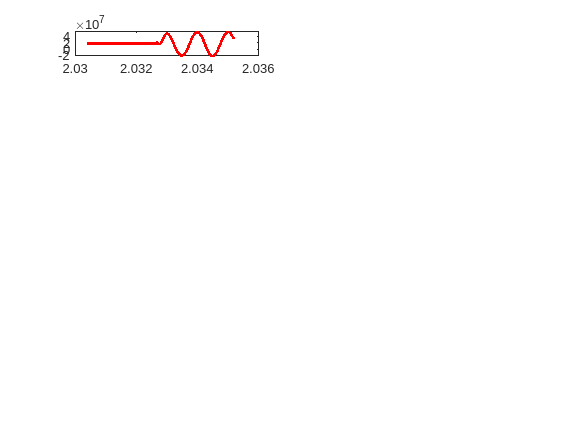

% Clear all figures
close all;

colorList = ["r" "g" "b" "c" "m" "#EDB120" "k"];

% Define directory containing the audio files
directory = 'ESP32/cppstreamer/BeamformerTest/SanityTest';
filename = fullfile(directory, 'mic_6_num_0');

%allMics = zeros(1,8);
fileID = fopen(filename);
data = fread(fileID,'single');

% Create a tiled layout for the subplots
t_layout = tiledlayout(7, 2);
sampleRate = 41666;
numSamples = 190;
numMics = 8;
micList = 0:6;
allAudio = cell(numMics, 1);

% Loop through each audio file
for m = 1:7
    % Construct file name
    filename = fullfile(directory, sprintf('mic_%d.wav', i));
    
    onePacketLength = numSamples*numMics ;
    numPacketsInData = floor(length(data)/onePacketLength);
    micData = zeros(numSamples,1);
    for i = 0:numPacketsInData-1
        micData = [micData; data(1+(micList(m)*numSamples)+i*onePacketLength:(micList(m)*numSamples)+i*onePacketLength+numSamples)];
    end

    % Read audio file
    micData = micData((numSamples+1):8*sampleRate);
    audio = micData;
    allAudio{m} = micData;
     
    
    % Time vector
    t = (0:length(audio)-1) / 41666;
    
    % Create the next tile in the tiled layout
    nexttile;
    % Plot audio
    plot(t(84600:84800), audio(84600:84800), LineWidth=2, Color=colorList(m));
    %plot(t(84650:84720), audio(84650:84720), LineWidth=2, Color=colorList(m));
    [mag, index] = max(audio(84650:84720));
    hold on
    xline(t(84650+index))
    hold off
    grid on



    if m == 7
        xlabel('Time (s)', 'FontSize', 8);
    end
    if m~=7
        xticklabels([]);
    end
    ylim([-1.5*power(10, 8) 1.5*power(10, 8)])
    ylabel('Amplitude', 'FontSize', 8);
    title(sprintf('Q_%d', m), 'FontSize', 8);

    % Calculate FFT
    N = length(audio);
    Y = fft(audio);
    P2 = abs(Y/N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = sampleRate*(0:(N/2))/N;
    
    % Create the next tile in the tiled layout
    nexttile;
    
    % Plot FFT
    plot(f, mag2db(P1)-max(mag2db(P1)), LineWidth=2, Color=colorList(m));
    grid on

    %ytickList = linspace(0, 4e7,5);
    %yticks(ytickList(1:1:end))
    %yticklabels(string(ytickList(1:1:end)/10e6)+'e7')
    xtickList = linspace(0,2e3,5);
    xticks(xtickList(1:1:end))
    xticklabels([]);
    ylim([-80 0]);

    if m == 7
        xlabel('Frequency (Hz)', 'FontSize', 8);
        xticklabels(string(xtickList(1:1:end)))
    end
    if m~=7
        %xticklabels([]);
        
    end
    ylabel('Magnitude', 'FontSize', 8);
    xlim([1 2000])
    %ylim([0 4*power(10, 7)])
    
    title(sprintf('Q_%d', m), 'FontSize', 8);
    
end



t_layout.TileSpacing = 'compact';
t_layout.Padding = 'compact';

% Adjust the figure size
set(gcf,'Visible','on', 'Units', 'centimeters','OuterPosition', [0 0 18 30])

% Export the figure to PDF
exportgraphics(gcf,'wavSanity.pdf')
